## 0. Initialization

**Cleaning the environment**

clear; close all; clc;

**Installation and import**

Download and unzip the content of the folder `'LoopDetect_for_Matlab'`. Within the MATLAB session, navigate to this folder and work there or add the path of the folder to MATLAB's search path for the current MATLAB session by MATLAB's `addpath()` function. Deending on where you stored the folder, its name could be something like `'/Users/Desktop/LoopDetect' `on Mac or `'C:\matlab\LoopDetect'` on Windows.

% Retrieve the LoopDetect folder location when having navigated to the folder
% within the MATLAB session.
LoopDetect_Folder_Name = fullfile(pwd, '..', 'LoopDetect_2025', 'src', 'loopdetect_for_matlab');
LoopDetect_Folder_Name = char(java.io.File(LoopDetect_Folder_Name).getCanonicalPath); % normalize path
addpath(LoopDetect_Folder_Name);

**Models:**

Models = fullfile(pwd, '..', 'LoopDetect_2025', 'src', 'models');
Models = char(java.io.File(Models).getCanonicalPath); % normalize path
addpath(Models);

## 1. Model

Model: mPOSm4 is already implemented in `loop_detect_for_matlab`` and can be access through: `@(x)func_POSm4(1,x,klin,knonlin)`

Parameters:

s_star = [1,1,1,1]'; % # Dummy steady state for initialization
klin = [150, 0.04, 0.3, 500, 5000, 80, 4, 5];
knonlin = [0.3,2]

knonlin =     0.3000    2.0000


## 2. Result reproduction

### **Loop structure:**

loop_list=find_loops_vset(@(x)func_POSm4(1,x,klin,knonlin),s_star,10);
disp(loop_list{1})

        loop         length    sign
    _____________    ______    ____

    {[4 1 2 3 4]}      4        -1 
    {[  4 2 3 4]}      3         1 
    {[      1 1]}      1        -1 
    {[      2 2]}      1        -1 
    {[      3 3]}      1        -1 
    {[      4 4]}      1        -1 



first_loop=loop_list{1}.loop{1}

first_loop =      4     1     2     3     4


disp(loop_summary(loop_list{1}))

                length_1    length_2    length_3    length_4
                ________    ________    ________    ________

    total          4           0           1           1    
    negative       4           0           0           1    
    positive       0           0           1           0    



Filter loops:

noi = 2;
loops_with_node2=loop_list{1}(...
    cellfun(@(z) ismember(noi,z),loop_list{1}.loop),:)

loops_with_node2 = 3×3 table
        loop         length    sign
    _____________    ______    ____

    {[4 1 2 3 4]}      4        -1 
    {[  4 2 3 4]}      3         1 
    {[      2 2]}      1        -1 


Search a loop list for loops containing specific edges defined by the indices of the ingoing and outgoing nodes. This example returns the indices of all loops with a regulation of node 3 by node 2. These are only two here.

loop_edge_ind=find_edge(loop_list{1},2,3);
loops_with_edge_2_to_3=loop_list{1}(loop_edge_ind,:)

loops_with_edge_2_to_3 = 2×3 table
        loop         length    sign
    _____________    ______    ____

    {[4 1 2 3 4]}      4        -1 
    {[  4 2 3 4]}      3         1 


for i=1:2
    disp(loops_with_edge_2_to_3.loop{i})
end

     4     1     2     3     4

     4     2     3     4



### **Jacobian matrix:**

The functions `numerical_jacobian()` and `numerical_jacobian_complex()` provide numerical estimates of the Jacobian matrix of an ODE system at a chosen state vector $s_{\ast }$. They implement, respectively, a **finite-difference method using real perturbations** and the **complex-step method**, the latter offering higher accuracy due to the absence of subtractive cancellation errors (see Martins *et al*., 2003) and making use of MATLAB’s built-in support for complex arithmetic.

The function handle **f** (in the example derived from `func_POSm4`, the positive-feedback chain model of Baum *et al*., 2016) must refer to a function that returns the vector of time derivatives,


$$f_i \left(s\right)=\frac{\;{\textrm{dS}}_i }{\textrm{dt}}\ldotp$$


When used with `numerical_jacobian_complex()`, this function is required to depend **only** on the state variables. Any additional dependencies—such as model parameters—must be fixed beforehand so that $f$ effectively maps only the variable vector $s$ to its corresponding derivative vector.

j_matrix=numerical_jacobian_complex(@(s)func_POSm4(1,s,klin,knonlin),...
s_star);
signed_jacobian=sign(j_matrix)

signed_jacobian =     -1     0     0    -1
     1    -1     0     1
     0     1    -1     0
     0     0     1    -1


Need to verify: Function `find_loops(j_matrix)` will give result with different data structure than `find_loops_vset(@(x)func(...), ...)`.

loop_list_2=find_loops(j_matrix)

loop_list_2 = 6×3 table
        loop         length    sign
    _____________    ______    ____

    {[4 1 2 3 4]}      4        -1 
    {[  4 2 3 4]}      3         1 
    {[      1 1]}      1        -1 
    {[      2 2]}      1        -1 
    {[      3 3]}      1        -1 
    {[      4 4]}      1        -1 


loop_list_2

loop_list_2 = 6×3 table
        loop         length    sign
    _____________    ______    ____

    {[4 1 2 3 4]}      4        -1 
    {[  4 2 3 4]}      3         1 
    {[      1 1]}      1        -1 
    {[      2 2]}      1        -1 
    {[      3 3]}      1        -1 
    {[      4 4]}      1        -1 


loop_list

loop_list = 1×1 cell array
    {6×3 table}


### Temporal dynamics

Solving the ODE model to observe temporal dynamics

tspan = linspace(0, 9.5, 9501);
opts = odeset('RelTol',1e-6,'AbsTol',1e-9);  % closer to typical SciPy accuracy
[t,sol] = ode15s(@(t,x) func_POSm4(t,x,klin,knonlin), tspan, s_star, opts);
s_star=sol(end,:); %the last point of the simulation is chosen
tspan = linspace(0, 11, 11001);
[t,sol] = ode15s(@(t,x) func_POSm4(t,x,klin,knonlin), tspan, s_star, opts);

Plot

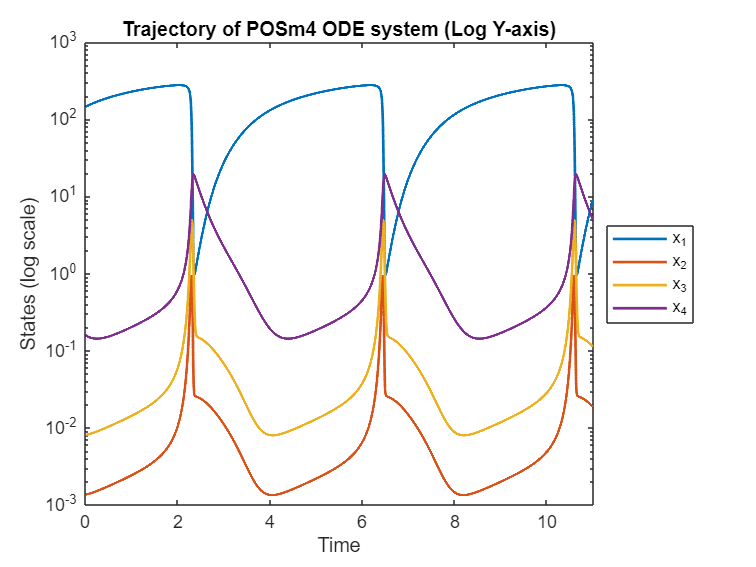

figure;
semilogy(t, sol, 'LineWidth', 1.5);
xlabel('Time');
ylabel('States (log scale)');
xlim([0,11]);
title('Trajectory of POSm4 ODE system (Log Y-axis)');
legend('x_1','x_2','x_3','x_4','Location','eastoutside'); % southeast

### Pertubation Analysis

t0  = 8.6;
idx0 = 86;
cap = 0.05;
dt  = 1e-4;

tpre  = (-cap:dt:0)';
tpost = (0:dt:cap)';
x0_pre = sol(855, :);
[tpre_out, ypre] = ode15s(@(tt,xx) func_POSm4(tt, xx, klin, knonlin), tpre, x0_pre(:), opts);

x0_post = sol(860, :);
x0_post(4) = 0.75;
[tpost_out, ypost] = ode15s(@(tt,xx) func_POSm4(tt, xx, klin, knonlin), tpost, x0_post(:), opts);

t_all = [tpre_out; tpost_out(2:end)];
y_all = [ypre;     ypost(2:end,:)];

Plot

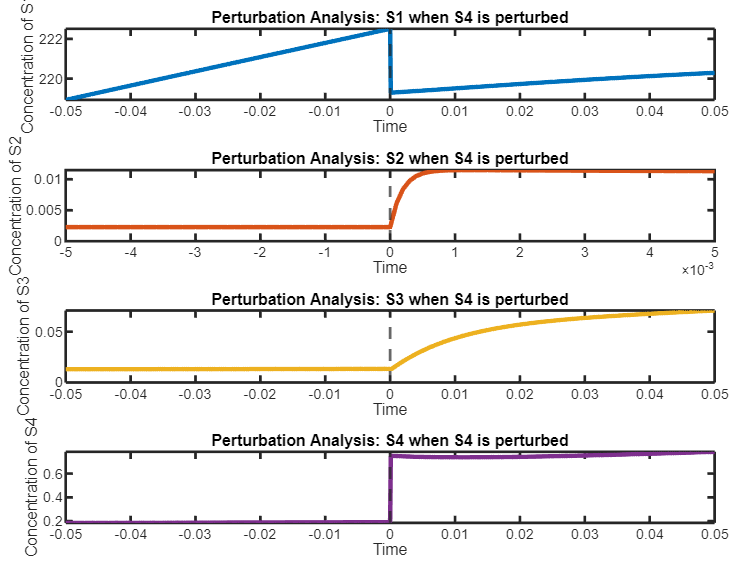

figure;

% Can change this to a colors array later. Defaults setting:
colors = lines(4);

tiledlayout(4,1,'TileSpacing','compact','Padding','compact');

for k = 1:4
    nexttile;

    % Special case: state 2
    if k == 2
        xlim_vals = [-0.005, 0.005];
        ticks_seq = -0.005:0.001:0.005;
    else
        xlim_vals = [-0.05, 0.05];
        ticks_seq = -0.05:0.01:0.05;
    end

    plot(t_all, y_all(:,k), 'LineWidth', 2.5, 'Color', colors(k,:));
    hold on;
    xline(0, '--', 'LineWidth', 1.5);
    hold off;

    xlim(xlim_vals);
    xticks(ticks_seq);

    xlabel('Time');
    ylabel(sprintf('Concentration of S%d', k));
    title(sprintf('Perturbation Analysis: S%d when S4 is perturbed', k));

    box on;
    set(gca,'LineWidth',1.5);  % thicker axis box like R's box(lwd=2)
end


%exportgraphics(gcf,'model_1_perturbation.png','Resolution',300);

## Export *.mlx to *.md / *.pdf

path = export("MATLAB/model_1_POSm4.mlx", "MATLAB/model_1_POSm4.pdf")

path = 'MATLAB\model_1_POSm4.pdf'

mdfile = export("MATLAB/model_1_POSm4.mlx","MATLAB/model_1_POSm4.md", Format="markdown", EmbedImages=true, ...
    AcceptHTML=true)

mdfile = 'MATLAB\model_1_POSm4.md'